## WirelessNetwork Documentation -- Example #1

The purpose of this Live Editor document is to provide a first example of a complete wireless network that is representative of what you will need to turn in for your preliminary design.  This example does not use sectorization (see example #2 for that).

It is assumed that you have worked through the first two documents that describe how to create and use a `WirelelessNetwork` object, but you don't need to go through the third document on sectorization (which is covered in the second example).

# Creating a WirelessNetwork Object

We begin by creating a `WirelessNetwork` object and assign it to `net`, which is the name of the variable that describes our network.  To do this, type the following:

net = WirelessNetwork

net =   WirelessNetwork with properties:

           bs_locations: []
            bs_channels: []
           bs_power_dBm: []
           channel_sets: []
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


# Managing Channels

The next step is to group the chanels that you purchased into "`channel_sets`".   The vector called `channel_sets` specifies how many channels are in a particular set.  This is important because cells are assigned channel sets rather than individual channels.  Later, when we create our base stations, we will need to indicate which channel set to associate with the base station.

Suppose that we have purchased the licenses to 20 RF channels.  Moreover, suppose that we do not plan to use sectorization (see the other example for sectorization) and that we would like to have 4 channel sets (think of this as clusters of size N=4).   Because 20 is divisible by 4, each station can have the same number of channels.

We can specify our channel sets as a vector containing four 6s.  We can order those numbers however we like, for instance:

net.channel_sets = [5 5 5 5]

net =   WirelessNetwork with properties:

           bs_locations: []
            bs_channels: []
           bs_power_dBm: []
           channel_sets: [5 5 5 5]
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


As a sanity check, please verify that the total number of channels in the channel set does not exceeed the number of channels you are willing to purchasing (keeping in the mind the cost to license each channel):

total_channels = sum(net.channel_sets)

total_channels = 20

# Estimating the Number of Base Stations

Before we start placing our base stations, we need to estimate how many we can afford.  As described in WirelessProjectPart1.mlx, each base station has a fixed cost of $250,000 (meant to include the cost of the property it is located on, the tower struture, and the networking/power resources provided to it) plus $25,000 per RF channel's transciever (meant to be the cost of the radio equipment).   Because our channel sets all use 5 channels, the cost of each base station is 250+5*25=$375,000.   

Suppose our total budget is $20,000,000.  We have licensed 20 RF channels, which cost $500,000 each.  Thus the cost of our spectrum licenses is 24*500 = $10,000,000.  Given our overall budget, this leaves $10,000,000 for base stations.  We can afford 10000/375 = 26.67 base stations. We will have to round down and only buy 26 base stations to remain within our budget.

# Adding the First Cluster of Base Stations

net.CreateCentralCluster(4,0)

ans =   WirelessNetwork with properties:

           bs_locations: [4×1 double]
            bs_channels: [4×1 double]
           bs_power_dBm: [4×1 double]
           channel_sets: [5 5 5 5]
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


bs_power_dBm = 30 * ones(28,1)

bs_power_dBm =     30
    30
    30
    30
    30
    30
    30
    30
    30
    30
    30
    30
    30
    30
    30


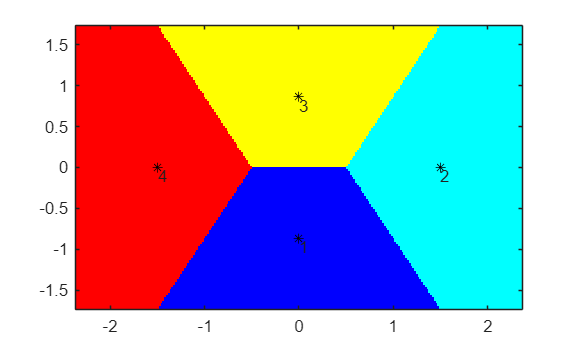

net.SetPower(bs_power_dBm)
net.MapCoverage

# Adding the First Layer of Interferance

net.CreateFirstTier(4)

ans =   WirelessNetwork with properties:

           bs_locations: [28×1 double]
            bs_channels: [28×1 double]
           bs_power_dBm: [28×1 double]
           channel_sets: [5 5 5 5]
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


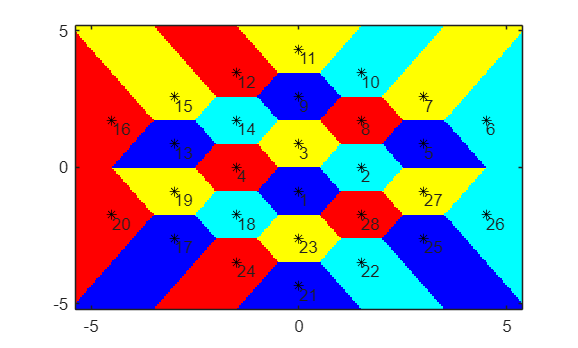

net.SetPower(bs_power_dBm)
net.MapCoverage

# Centering Network on Map

bs_expanded = 60*net.bs_locations;
bs_shift = bs_expanded + 300 + 300*1i;
net.bs_locations = bs_shift;

# Removing Base Stations

We would like to create a network containing 34 base stations that are each generated randomly like the first one.  We can do this in a loop that we go through 34 times, as follows:

Let's look at the net object to verify that it has 26 base stations:

net.RemoveBase(26)
net.RemoveBase(16)

net

net =   WirelessNetwork with properties:

           bs_locations: [26×1 double]
            bs_channels: [26×1 double]
           bs_power_dBm: [26×1 double]
           channel_sets: [5 5 5 5]
    sector_offset_angle: 0
         map_resolution: 250
              noise_dBm: -100
            pl_exponent: 3
            SINR_thresh: 10
         ms_per_channel: 10
              max_users: []
           map_filename: 'Morgantown'
          save_filename: 'MyProject'
                   cost: []


# Analyzing the Network

Let's confirm the cost of the network:

net.ComputeCost

ans = 19750

Due to the random selection of channel sets, it is possible that we have exceeded our budget.

Now let's generate some maps to show what this looks like.  Begin with a coverage map, making sure to increase the map resolution before drawing it:

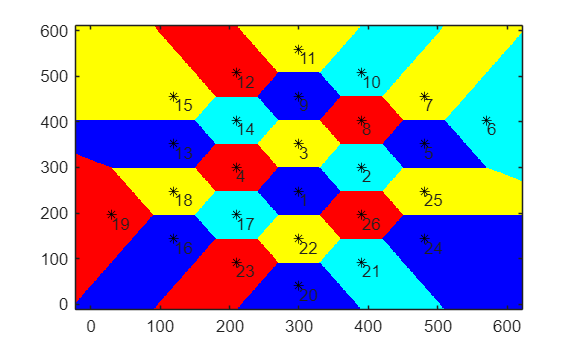

net.map_resolution = 600;
net.MapCoverage;

Next, map the SINR outage regions:

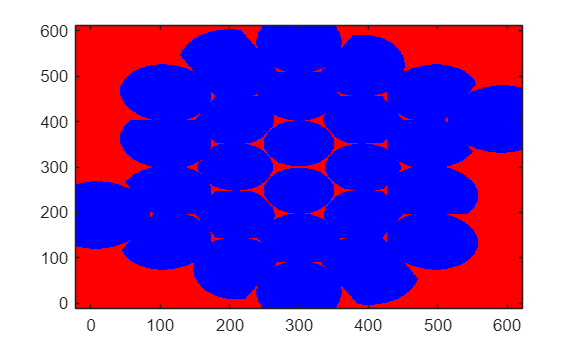

Covering 69.41 percent of the area with sufficient SINR
worst case SINR is 0.727890


net.MapSINR

Recall that this map shows you the regions where the SINR is below the threshold (in red).

Now, let's look at what our network looks like on a city map of Morgantown:

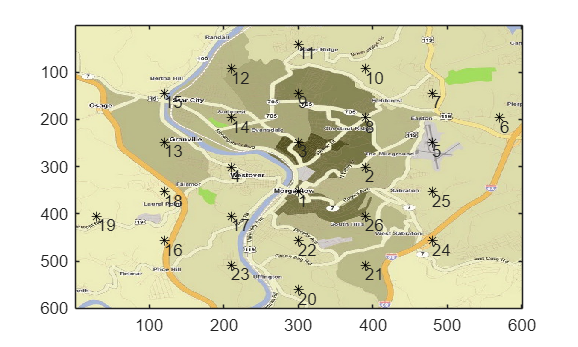

ans = struct with fields:
       cdata: [344×543×3 uint8]
    colormap: []


net.MapCity

Next, let's put mobiles onto the map.  Load the data file containing locations of our mobiles, and show them at the busiest hour (19:00):

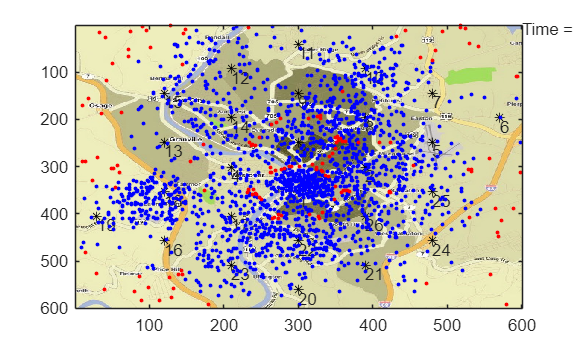

load( 'MobileLocationData' );
net.MapCity( ms_locations{19} );

Now let's put the mobiles onto our coverage map:

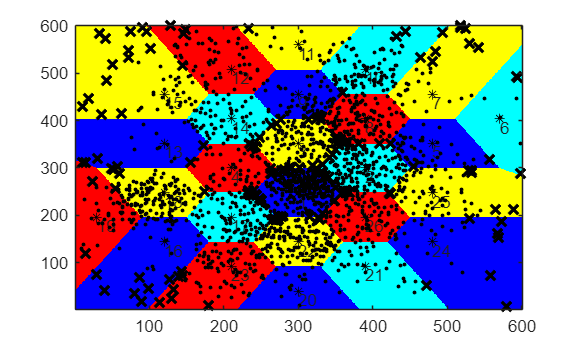

ans = struct with fields:
       cdata: [344×543×3 uint8]
    colormap: []


% show the mobiles at 19:00 on the coverage map
net.MapMobiles( ms_locations{19} )

Net, let's analyze the performance:

[num_connected, num_over_thresh] = net.AnalyzeNetwork( ms_locations )

num_connected =          440         363         275         182         227         391         523         691         850         805         793         929         964         872         868         898         971         971        1012         980         924         826         731         608


num_over_thresh =          455         377         275         182         227         419         564         833        1154        1021        1022        1483        1577        1304        1251        1335        1624        1669        1852        1719        1476        1149         923         686


Plot the total number of connected users, the number of call attempts, and the number over threshold (i.e., the number that are *covered*) on the same plot:

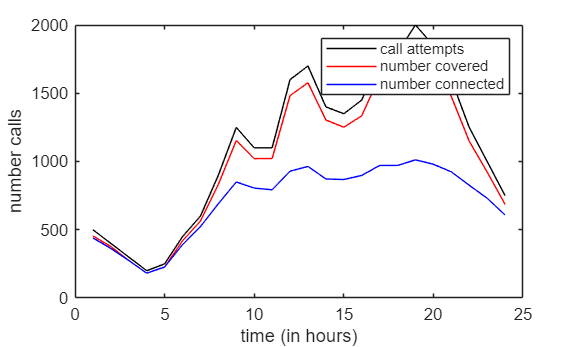

plot( 1:length(call_attempts), call_attempts, '-k', ...
    1:length(call_attempts), num_over_thresh, '-r', ...
    1:length(call_attempts), num_connected, '-b' );
xlabel( 'time (in hours)' );
ylabel( 'number calls' );
legend( 'call attempts', 'number covered', 'number connected' );

You may need to move the figure's legend so that it does not cover a curve.

Alternatively, we could plot the *fraction* of users that are covered and the fraction that are covered and connected:

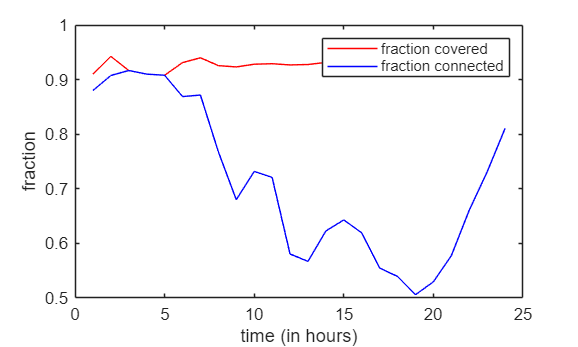

fraction_over_thresh = num_over_thresh./call_attempts;
fraction_connected = num_connected./call_attempts;
plot( 1:length(call_attempts), fraction_over_thresh, '-r', ...
    1:length(call_attempts), fraction_connected, '-b');
xlabel( 'time (in hours)' );
ylabel( 'fraction' );
legend( 'fraction covered', 'fraction connected');

If we want a single KPI (key performance indicator), it is the total number of connected users throughout the day:

sum(num_connected)

ans = 17094

The goal should be for this value to be close to the number of call attempts for the day

sum( call_attempts )

ans = 26550

The percentage of users that are connected can be echoed to the screen using:

percent_connected = sum(num_connected)/sum(call_attempts);
fprintf( 'The percentage connected is %2.2f%%\n', 100*percent_connected)

The percentage connected is 64.38%


# Saving the Network

Save your file using a name like PreliminaryDesign.mat

net.Save( "Preliminary.mat")
